# Heart Attack Project Code

## Feature Analysis and Plots

h_data = readmatrix("processedcleveland.csv"); 
data = h_data

data =    63.0000    1.0000    1.0000  145.0000  233.0000    1.0000    2.0000  150.0000         0    2.3000    3.0000         0    6.0000         0
   67.0000    1.0000    4.0000  160.0000  286.0000         0    2.0000  108.0000    1.0000    1.5000    2.0000    3.0000    3.0000    1.0000
   67.0000    1.0000    4.0000  120.0000  229.0000         0    2.0000  129.0000    1.0000    2.6000    2.0000    2.0000    7.0000    1.0000
   37.0000    1.0000    3.0000  130.0000  250.0000         0         0  187.0000         0    3.5000    3.0000         0    3.0000         0
   41.0000         0    2.0000  130.0000  204.0000         0    2.0000  172.0000         0    1.4000    1.0000         0    3.0000         0
   56.0000    1.0000    2.0000  120.0000  236.0000         0         0  178.0000         0    0.8000    1.0000         0    3.0000         0
   62.0000         0    4.0000  140.0000  268.0000         0    2.0000  160.0000         0    3.6000    3.0000    2.0000    3.0000    1.0000
   57.


% 5 random examples and all the feature names 
head(h_data, 5)

   63.0000    1.0000    1.0000  145.0000  233.0000    1.0000    2.0000  150.0000         0    2.3000    3.0000         0    6.0000         0
   67.0000    1.0000    4.0000  160.0000  286.0000         0    2.0000  108.0000    1.0000    1.5000    2.0000    3.0000    3.0000    1.0000
   67.0000    1.0000    4.0000  120.0000  229.0000         0    2.0000  129.0000    1.0000    2.6000    2.0000    2.0000    7.0000    1.0000
   37.0000    1.0000    3.0000  130.0000  250.0000         0         0  187.0000         0    3.5000    3.0000         0    3.0000         0
   41.0000         0    2.0000  130.0000  204.0000         0    2.0000  172.0000         0    1.4000    1.0000         0    3.0000         0




% DATA SIZE: (303 x 14)

m = 14;
% columnNames = data.Properties.VariableNames;
% commenting out for now
columnNames = {'age', 'sex', 'cp', 'trtbps', 'chol', 'fbs', 'restecg', 'thalachh', 'exng', 'oldpeak', 'slope', 'caa', 'thall', 'output'};



% Missing Values
missingCounts = sum(ismissing(data));
disp('Missing Values per Column:');

Missing Values per Column:


for i = 1:length(columnNames)
   fprintf('%-15s: %d\n', columnNames{i}, missingCounts(i));
end

age            : 0
sex            : 0
cp             : 0
trtbps         : 0
chol           : 0
fbs            : 0
restecg        : 0
thalachh       : 0
exng           : 0
oldpeak        : 0
slope          : 0
caa            : 0
thall          : 0
output         : 0


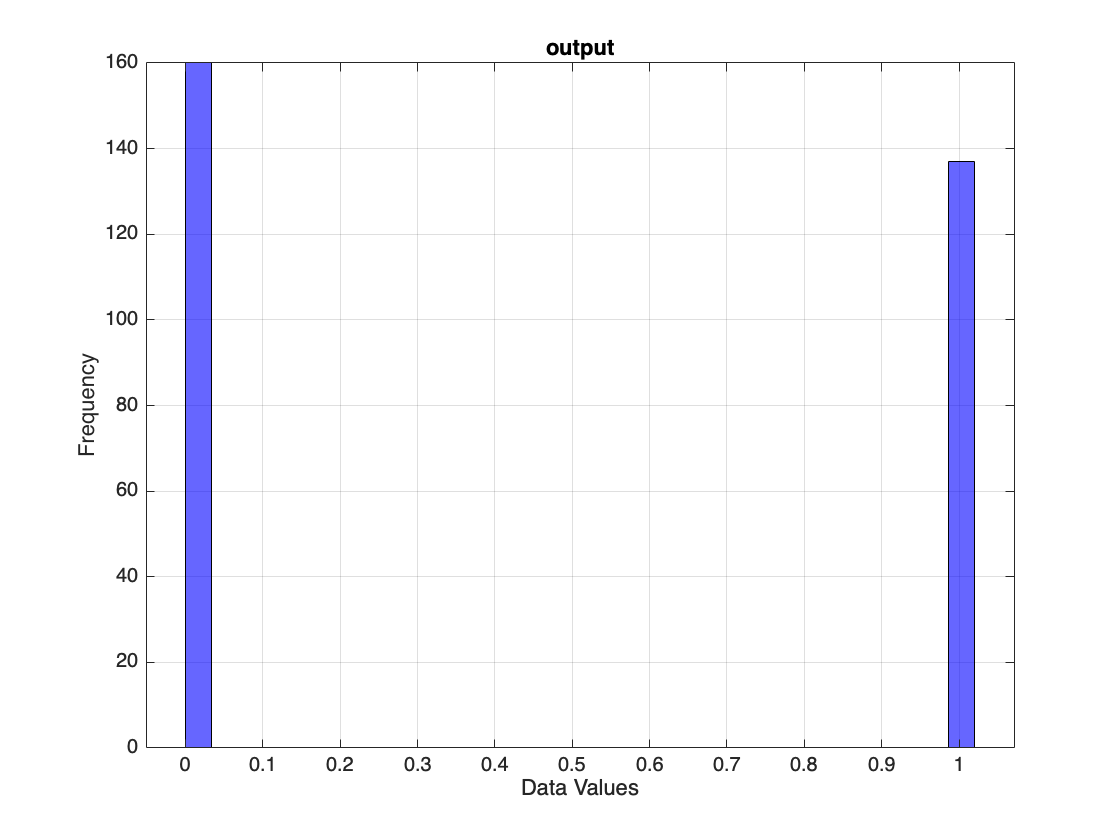


% Feature Distribution
% This  may take a while to run
for i = 1 : m
    plotHistogram(h_data(:, i), columnNames{i})
end

disp('Histograms Complete!')

Histograms Complete!



% Correlation Matrix

% Feature Scaling

## Initializing Data

% Initialize Data
X = h_data(:, 1:13);
[m,n] = size(X);
X = [ones(m,1), X];
y = h_data(:,end);


% Train Test Split
X_rand = X(randperm(size(X, 1)), :);
y_rand = y(randperm(size(y, 1)), :);

train = .6;
cv = .2;
% test = .2;


train_split = round(m*train);
cv_split = round(m*cv);
% test_split = round(m*test);


X_train = X_rand(1:train_split,:);
X_cv = X_rand(train_split:train_split+cv_split,:);
X_test = X_rand(train_split+cv_split:m,:);

y_train = y_rand(1:train_split,:);
y_cv = y_rand(train_split:train_split+cv_split,:);
y_test = y_rand(train_split+cv_split:m,:);

## Unregularized Logistic Regression Model

%======================Log Unreg Gradient Descent========================%

% Function Calls
initial_theta = zeros(n+1,1);

% Initialize fitting parameters
initial_theta = zeros(size(X_train, 2), 1);

% Set Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, cost] = ...
    fminunc(@(t)(costFunctionUnReg(t, X, y)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.344594



fprintf('Thetas\n');

Thetas


fprintf(' %f \n', theta); 

 -7.372045 
 -0.014164 
 1.312073 
 0.575898 
 0.024044 
 0.004995 
 -1.021918 
 0.245153 
 -0.020665 
 0.926104 
 0.247386 
 0.570009 
 1.267718 
 0.343937 


% Accuracy Checking

p_train = predict(theta, X_train);
train_accuracy = mean(double(p_train == y_train)) * 100;
fprintf('Training Accuracy: %f\n', train_accuracy);

Training Accuracy: 52.247191



p_test = predict(theta, X_test);
test_accuracy = mean(double(p_test == y_test)) * 100;
fprintf('Test Accuracy: %f\n', test_accuracy);

Test Accuracy: 55.737705


## Regularized Logistic Regression Model

%======================Log Reg Gradient Descent========================%


% Function Calls
initial_theta = zeros(n+1,1);

% Initialize fitting parameters
initial_theta = zeros(size(X_train, 2), 1);

% Set regularization parameter lambda
lambda = 5;

% Set Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, J, exit_flag] = ...
        fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.344594


fprintf('Thetas\n');

Thetas


fprintf(' %f \n', theta); 

 -4.711711 
 -0.013156 
 0.604306 
 0.500985 
 0.018056 
 0.003112 
 -0.322208 
 0.237367 
 -0.022562 
 0.519339 
 0.319804 
 0.268992 
 0.910606 
 0.386047 


%===================================================================%


% Accuracy Checking

p_train = predict(theta, X_train);
train_accuracy = mean(double(p_train == y_train)) * 100;
fprintf('Training Accuracy: %f\n', train_accuracy);

Training Accuracy: 50.000000


p_test = predict(theta, X_test);
test_accuracy = mean(double(p_test == y_test)) * 100;
fprintf('Test Accuracy: %f\n', test_accuracy);

Test Accuracy: 55.737705


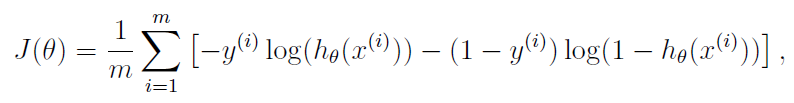

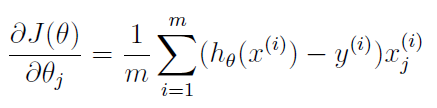

%=======================================LOG UNREG COST FUNCTION=============================================%
function [J, grad] = costFunctionUnReg(theta, X, y)

m = length(y);

% J = 0;
% grad = zeros(size(theta));

h = sigmoid(X*theta);

J = (1/m*sum(-y.*log(h)-(1-y).*log(1-h)));

grad = (1/m) * (X' * (h - y));

end
%===========================================================================================================%

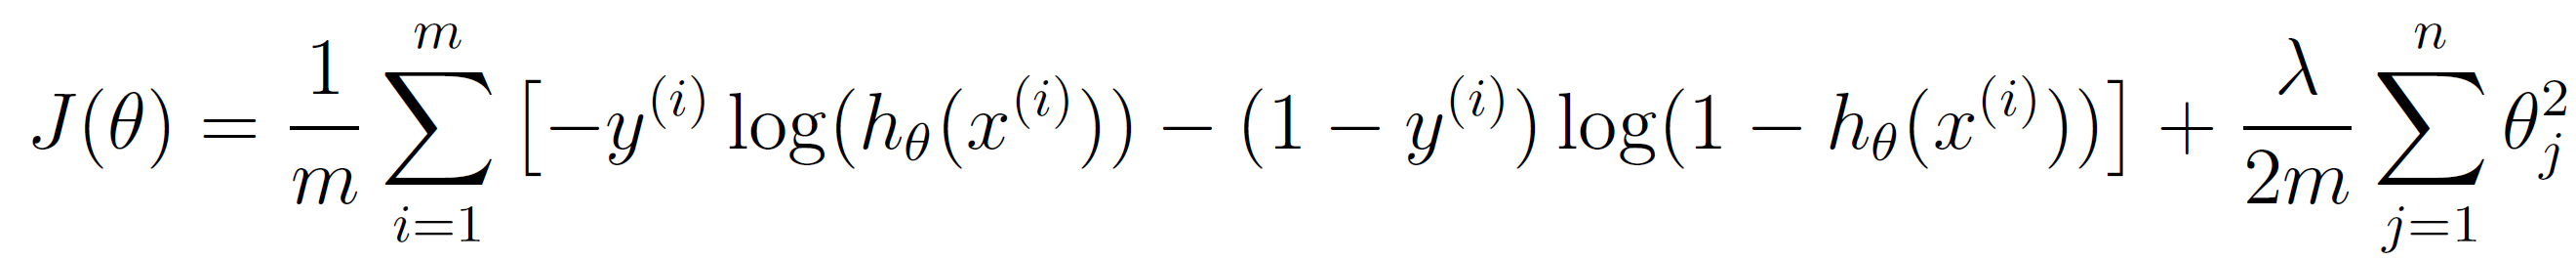

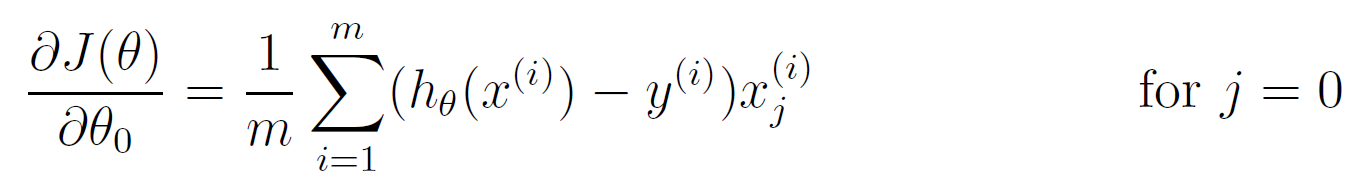

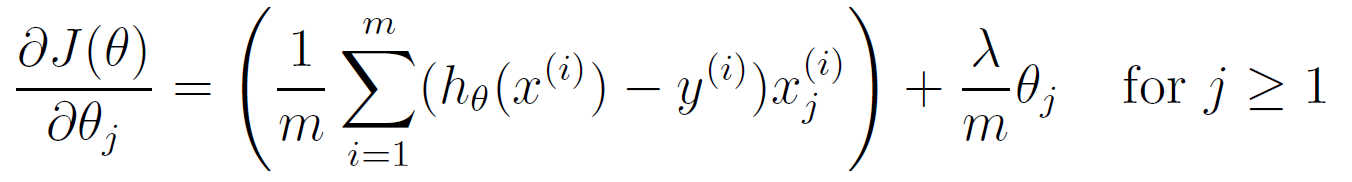

%====================================REG LOG COST FUNCTION=============================================%
function [J, grad] = costFunctionReg(theta, X, y, lambda)

m = length(y); % number of training examples
 
% J = 0;
% grad = zeros(size(theta));

h = sigmoid(X*theta);

J = (1/m*sum(-y.*log(h)-(1-y).*log(1-h)));
J = J + (lambda/(2*m)) * sum(theta(2:end).^2);

grad = (1/m) * (X' * (h - y));
grad(2:end) = grad(2:end) + (lambda/m) * theta(2:end);

end

%=====================================================================================================%


%==============SIGMOID FUNCTION===============%

function g = sigmoid(z)

g = zeros(size(z));
g = 1./(1+exp(-z)); %g = 1./(1+e.^(-z))

end

%=============================================%

%==============PREDICT FUNCTION===============%

function p = predict(theta, X)

m = size(X,1);
p = zeros(m, 1);

h = sigmoid(X*theta);
p(h>=0.5) = 1;

end

%=============================================%

function plotHistogram(data, plotTitle)
    % plotHistogram creates a histogram for the input data array with a title.
    % Inputs:
    %   - data: Array of numeric data to be visualized in the histogram
    %   - plotTitle: String for the title of the plot

    % Create the histogram
    histogram(data, 'NumBins', 30, 'FaceColor', 'blue', 'EdgeColor', 'black');

    % Customize the appearance
    xlabel('Data Values');
    ylabel('Frequency');
    title(plotTitle);
    grid on;
end